%MODELLO PREVISIONALE SEDE FISCIANO
clc
clear all
load('workspace.mat')

tic
% IMPORT DATI ANNUALI 2017
timeSeries= '2017_2023.xlsx';
[timeSeries] = importdata(timeSeries);
x=linspace(1,length(timeSeries),length(timeSeries))';

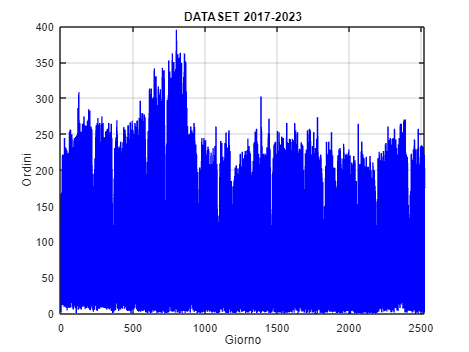

%Grafico Serie storica
figure(1)
plot(x,timeSeries,'-b',LineWidth=0.3)
xlim([0 2525])
ylim([0 400])
grid on
xlabel('Giorno')
ylabel('Ordini')
title('DATASET 2017-2023')

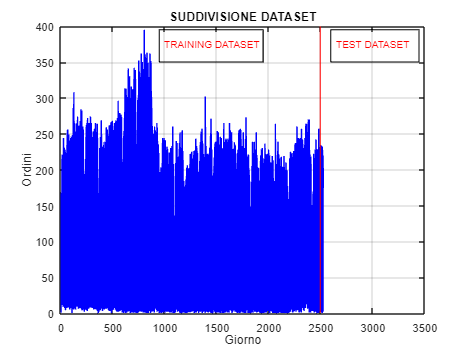

%Grafico Serie storica
figure(1)
plot(x,timeSeries,'-b',LineWidth=0.3)
xlim([0 3500])
ylim([0 400])
grid on
xlabel('Giorno')
ylabel('Ordini')
title('SUDDIVISIONE DATASET')
% Aggiungi la linea rossa verticale
x_value = 2495; % Punto x della linea verticale
line([x_value x_value], ylim, 'Color', 'r', 'LineWidth', 1); % Aggiungi la linea rossa verticale

% Aggiungi etichette con rettangolo
text_pos_training = [x_value - 1550, 350, 1000, 45]; % Posizione e dimensioni del rettangolo per "TRAINING DATASET"
text_pos_test = [x_value + 100, 350, 850, 45]; % Posizione e dimensioni del rettangolo per "TEST DATASET"
rectangle('Position', text_pos_training, 'EdgeColor', 'black', 'LineWidth', 1); % Rettangolo per "TRAINING DATASET"
rectangle('Position', text_pos_test, 'EdgeColor', 'black', 'LineWidth', 1); % Rettangolo per "TEST DATASET"
text(x_value - 1500, 375, 'TRAINING DATASET', 'Color', 'red', 'FontSize', 9); % Etichetta "TRAINING DATASET"
text(x_value + 150, 375, 'TEST DATASET', 'Color', 'red', 'FontSize', 9); % Etichetta "TEST DATASET"

%----------------MODELLO PREDITTIVO BASATO SU MACHINE LEARNING-------------%

% Definizione della finestra temporale per la previsione
windowSize = 30;

% Creazione di variabili predittive e variabile di risposta
predictors = zeros(length(timeSeries) - windowSize, windowSize);
response = zeros(length(timeSeries) - windowSize, 1);

for i = 1:(length(timeSeries) - windowSize)
    predictors(i, :) = timeSeries(i:i+windowSize-1)';
    response(i) = timeSeries(i+windowSize);
end

% Divisione dei dati in set di addestramento e test
minTrainingDataSize = 2465;
trainingDataSize = min(minTrainingDataSize, length(timeSeries) - windowSize);

trainingData = predictors(1:trainingDataSize, :); %set di addestramentro
testData = predictors(trainingDataSize + 1:end, :);   %set di Test
responseTrain = response(1:trainingDataSize, :); %set di addestramentro
responseTest = response(trainingDataSize + 1:end, :);  %set di Test


% Definizione della griglia dei parametri
numEstimators = [50, 100, 150]; %numero di alberi nella foresta
maxDepth = [5, 10, 20]; % massima profondità di ciascun albero
rng=42;  %seme fisso per rendere riproducibili i risultati

% Inizializzazione delle variabili per il miglior modello
bestModel = [];
bestRMSE = Inf;
bestNumTrees = 0;
bestMaxSplits = 0;  % Dichiarazione di maxSplits

% Grid Search
for i = 1:numel(numEstimators)
    numTrees = numEstimators(i);

    for j = 1:numel(maxDepth)
        depth = maxDepth(j);

        % Inizializzazione dell'array per i risultati di k-fold RMSE
        kfoldRMSE = zeros(1, 5); % 5-fold cross-validation

        % Addestramento del modello con cross-validation
        cv = cvpartition(responseTrain, 'KFold', 5, 'Stratify', false);

        for fold = 1:cv.NumTestSets
            trainIdx = training(cv, fold);
            testIdx = test(cv, fold);

            % Addestramento del modello sul fold di training
            model = TreeBagger(numTrees, trainingData(trainIdx, :), responseTrain(trainIdx), 'Method', 'regression', 'NumPredictorsToSample', 'all', 'Options', statset('UseParallel', true), 'MaxNumSplits', depth);  % Senza 'Weights'

            % Predizione sul fold di test
            predictedTest = predict(model, trainingData(testIdx, :));

            % Calcolo dell'RMSE per il fold corrente
            kfoldRMSE(fold) = sqrt(mean((predictedTest - responseTrain(testIdx)).^2));
        end

 % Calcolo dell'RMSE medio sulla cross-validation
        meanRMSE = mean(kfoldRMSE);

 % Selezione del miglior modello
        if meanRMSE < bestRMSE
            bestRMSE = meanRMSE;
            bestModel = model;
            bestNumTrees = numTrees;
            bestMaxSplits = depth;
        end
    end
end


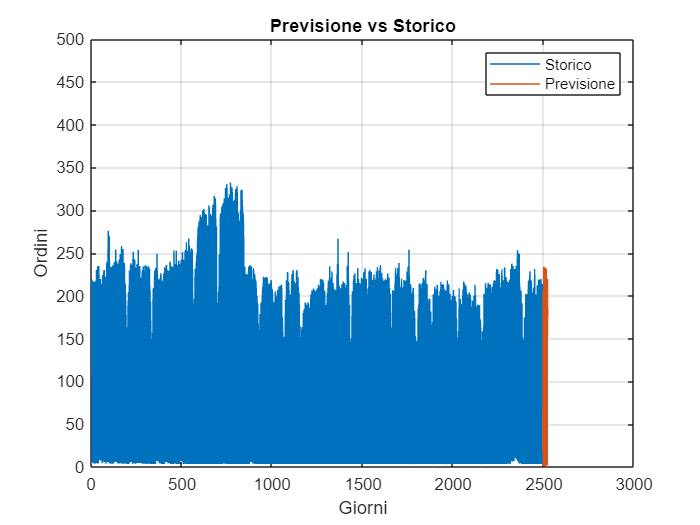

%-----------------------PREVISIONE VS STORICO--------------%
% Utilizza il modello migliore per effettuare previsioni su tutto il dataset

allDataPredictions = predict(bestModel, predictors);

figure;
plot(allDataPredictions, 'DisplayName', 'Storico' );
hold on;
plot( 2496:2525 , responseTest, 'DisplayName', 'Previsione');
title('Previsione vs Storico');
xlabel('Giorni');
ylabel('Ordini');
legend('show');
grid on;
hold off;
ylim([0, 500]);

%---------------------------PREVISIONE ULTIMI 30 GIORNI---------%

% Predizione e Valutazione del Miglior Modello sui Dati di Test (Ultimi 30 Giorni)
predictedLast30Days = predict(bestModel, testData);
% Calcolo dell'RMSE sui dati di test (Ultimi 30 Giorni)
rmseLast30Days = sqrt(mean((predictedLast30Days - responseTest).^2, 'omitnan'));

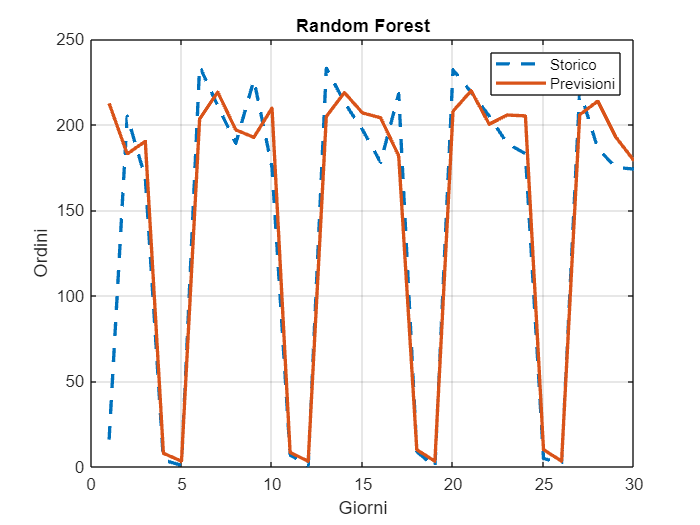



figure;
plot(responseTest, 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--'); % Linea tratteggiata per lo storico
hold on;
plot(predictedLast30Days, 'DisplayName', 'Previsioni', 'LineWidth', 2); % Linea continua per le previsioni
title('Random Forest');
xlabel('Giorni');
ylabel('Ordini');
legend('show');
grid on;
hold off;

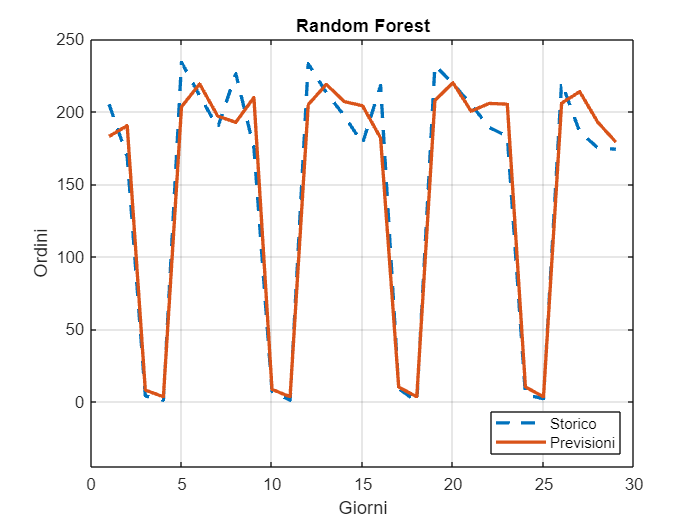

figure;
plot(responseTest(2:end), 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--'); % Linea tratteggiata per lo storico
hold on;
plot(predictedLast30Days(2:end), 'DisplayName', 'Previsioni', 'LineWidth', 2); % Linea continua per le previsioni
title('Random Forest');
xlabel('Giorni');
ylabel('Ordini');

legend('show');
lgd = legend('Location', 'southeast');
ylim([-45;250]);
grid on;
hold off;

% Specifica la directory di destinazione
videoDir = 'C:\Users\Sara\Desktop\grafici\GRAFICI NUOVI\';

% Crea un oggetto VideoWriter
v = VideoWriter(fullfile(videoDir, 'previsione_randomm.mp4'), 'MPEG-4');
v.FrameRate = 5; % Imposta il numero di frame al secondo

% Apre il video per la scrittura
open(v);

% Numero di giorni nei dati
numDays = numel(responseTest);

% Crea il plot dello storico
figure;
plot(responseTest(2:end), 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--');
hold on;
title('Random Forest (50,20,42)');
xlabel('Giorni');
ylabel('Ordini');
ylim([-50 250]);
grid on;

% Inizializza la previsione come un vettore di NaN con la stessa lunghezza di responseTest
prediction = NaN(size(responseTest));

% Plotta lo storico
plot(responseTest(2:end), 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--');
hold on;

% Aggiungi lo storico al video
frame = getframe(gcf);
writeVideo(v, frame);

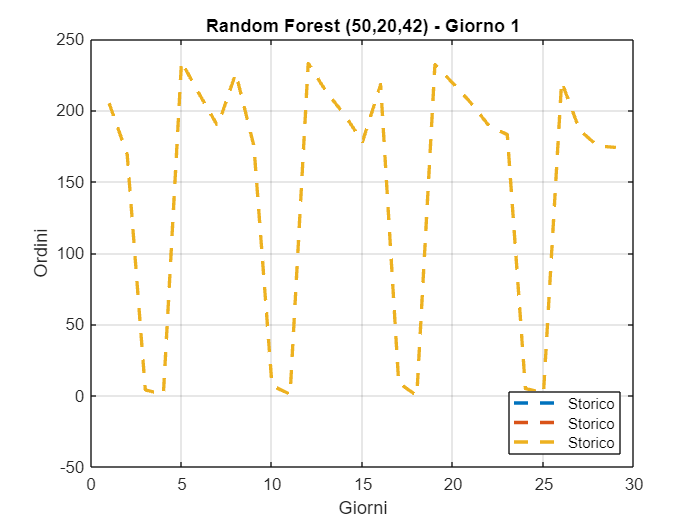

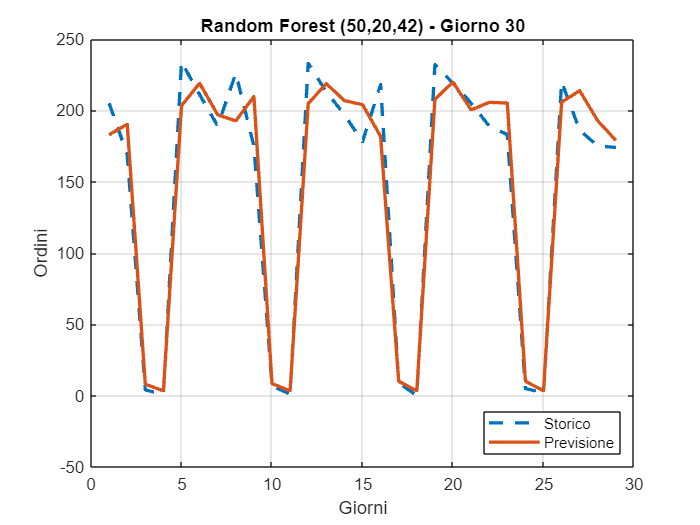


% Aggiungi il ritardo tra i frame per la creazione lenta
pause(1); % Ritardo di 1 secondo tra i frame

% Creazione del video delle previsioni
for i = 1:numDays
    % Aggiorna solo la previsione
    prediction(i) = predictedLast30Days(i);
    
    % Plotta solo la previsione
    plot(responseTest(2:end), 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--');
    hold on;
    plot(prediction(2:i), 'DisplayName', 'Previsione', 'LineWidth', 2);
    title(sprintf('Random Forest (50,20,42) - Giorno %d', i));
    xlabel('Giorni');
    ylabel('Ordini');
    ylim([-50 250]);
    legend('show');
    lgd = legend('Location', 'southeast');
    grid on;
    hold off;
    
    % Aggiorna la finestra di figura per visualizzare il nuovo frame
    drawnow;
    
    % Aggiungi il frame al video
    frame = getframe(gcf);
    writeVideo(v, frame);
    
    % Aggiungi il ritardo tra i frame per la creazione lenta
    pause(0.5); % Ritardo di 0.5 secondi tra i frame
end


% Chiudi il video
close(v);





fprintf('Best Model Parameters: NumEstimators = %d, MaxNumSplits = %d\n', bestNumTrees, bestMaxSplits);

Best Model Parameters: NumEstimators = 50, MaxNumSplits = 20


fprintf('RMSE on Last 30 Days Test Data: %f\n', rmseLast30Days);

RMSE on Last 30 Days Test Data: 40.241081


% Calcolo dell'RMSE sui dati di test (Ultimi 30 Giorni eliminando il primo)
rmseLast30Dayss = sqrt(mean((predictedLast30Days(2:end) - responseTest(2:end)).^2, 'omitnan'));
% Visualizzazione Grafica delle Previsioni rispetto ai Dati Reali sui Dati di Test (Ultimi 30 Giorni)
figure;
plot(responseTest(2:end), 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--'););

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

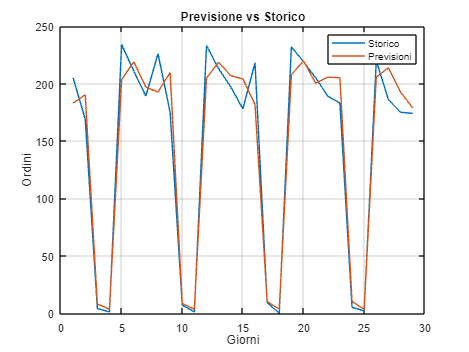

hold on;
plot( predictedLast30Days(2:end), 'DisplayName', 'Previsioni', 'LineWidth', 2); 
title('Random Forest');
xlabel('Giorni');
ylabel('Ordini');
legend('show');
lgd = legend('Location', 'southeast');
ylim([-45;250]);
grid on;
hold off;


fprintf('RMSE on Last 30 Days Test Data: %f\n', rmseLast30Dayss);

RMSE on Last 30 Days Test Data: 18.570120


% Calcolo del coefficiente di determinazione (R-squared)
meanResponse = mean(responseTest(2:end));
ss_total = sum((responseTest(2:end) - meanResponse).^2);
ss_residual = sum((responseTest(2:end) - predictedLast30Days(2:end)).^2);
r2 = 1 - (ss_residual / ss_total);

fprintf('Coefficient of Determination (R-squared): %.4f\n', r2);

Coefficient of Determination (R-squared): 0.9577


elapsedTime = toc; % Ottieni il tempo trascorso
fprintf('Tempo trascorso: %.4f secondi\n', elapsedTime);

Tempo trascorso: 34.9651 secondi


save('workspace');

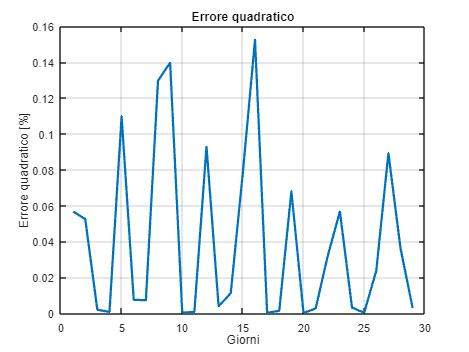

%errore quadratico
tot= sum(responseTest(2:end).^2);
for i=1:length(responseTest(2:end))
    err(i)= ((predictedLast30Days(i+1)-responseTest(i+1))^2)/tot;
end

err_100=err'*100;


figure;
plot(err_100,'LineWidth', 2);
title('Errore quadratico');
xlabel('Giorni');
ylabel('Errore quadratico [%]');
grid on;
hold off;

%cumulata dell errore %

num=0;

for i=1:length(responseTest(2:end));
    num(i)=(predictedLast30Days(i+1)-responseTest(i+1))^2;
   
end

a=sum(num);
cum_error=a/tot*100;

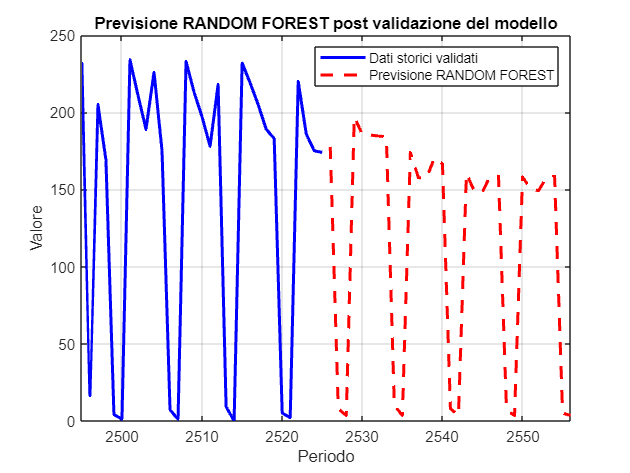

% Utilizza i dati noti come input per la previsione
lastKnownData = timeSeries(end - windowSize + 1:end);

% Previsione dei prossimi 30 periodi
numFuturePeriods = 31;
predictedFuture31Days = zeros(numFuturePeriods, 1);

for i = 1:numFuturePeriods
    % Utilizza il miglior modello per la previsione del prossimo periodo
    prediction = predict(bestModel, lastKnownData');

    % Aggiorna i dati noti con la previsione appena ottenuta
    lastKnownData = [lastKnownData(2:end); prediction];

    % Salva la previsione corrente
    predictedFuture31Days(i) = prediction;
end

% Visualizza le previsioni per i prossimi 30 giorni
figure;
plot(timeSeries, 'b', 'LineWidth', 2, 'DisplayName', 'Dati storici validati');
hold on;
plot([nan(size(timeSeries)); predictedFuture31Days], 'r--', 'LineWidth', 2, 'DisplayName', 'Previsione RANDOM FOREST');
xlabel('Periodo');
ylabel('Valore');
title('Previsione RANDOM FOREST post validazione del modello');
legend('show');
grid on;
xlim([2495, 2556]);

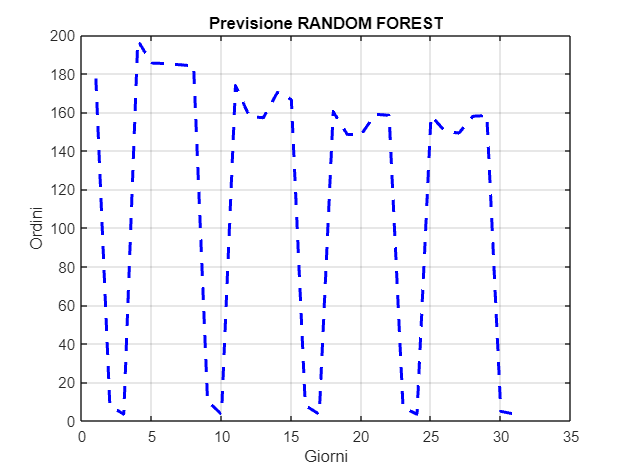

Giorni= linspace(1,length(predictedFuture31Days),length(predictedFuture31Days))';

figure;
plot(Giorni, predictedFuture31Days, 'b--', 'LineWidth', 2, 'DisplayName', 'Previsione');
hold on;
title('Previsione RANDOM FOREST');
xlabel('Giorni');
ylabel('Ordini');
grid on;

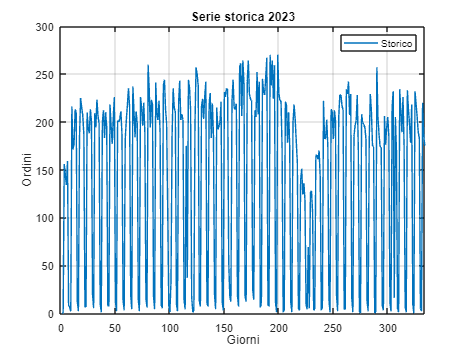

% Visualizzazione Grafica delle Previsioni rispetto ai Dati Reali sui Dati di Test (Ultimi 30 Giorni)
figure;
plot(timeSeries(2191:end), 'DisplayName', 'Storico');
title('Serie storica 2023');
xlabel('Giorni');
ylabel('Ordini');
legend('show');
grid on;
hold off;
xlim([0 334]);

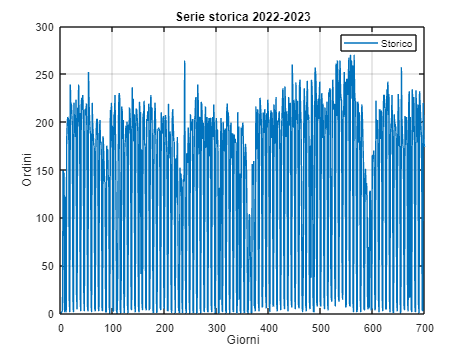

% Visualizzazione Grafica delle Previsioni rispetto ai Dati Reali sui Dati di Test (Ultimi 30 Giorni)
figure;
plot(timeSeries(1826:end), 'DisplayName', 'Storico');
title('Serie storica 2022-2023');
xlabel('Giorni');
ylabel('Ordini');
legend('show');
grid on;
hold off;

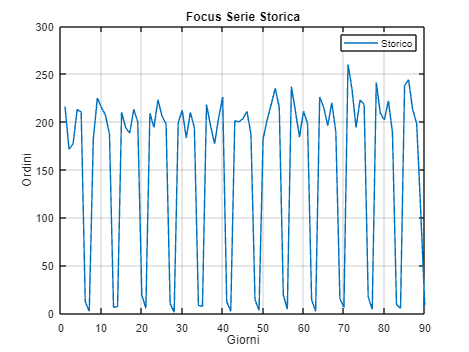

% Visualizzazione Grafica delle Previsioni rispetto ai Dati Reali sui Dati di Test (Ultimi 30 Giorni)
figure;
plot(timeSeries(2200:2300), 'DisplayName', 'Storico');
title('Focus Serie Storica');
xlabel('Giorni');
ylabel('Ordini');
legend('show');
grid on;
hold off;
xlim([0 90]);